## 5.2.1

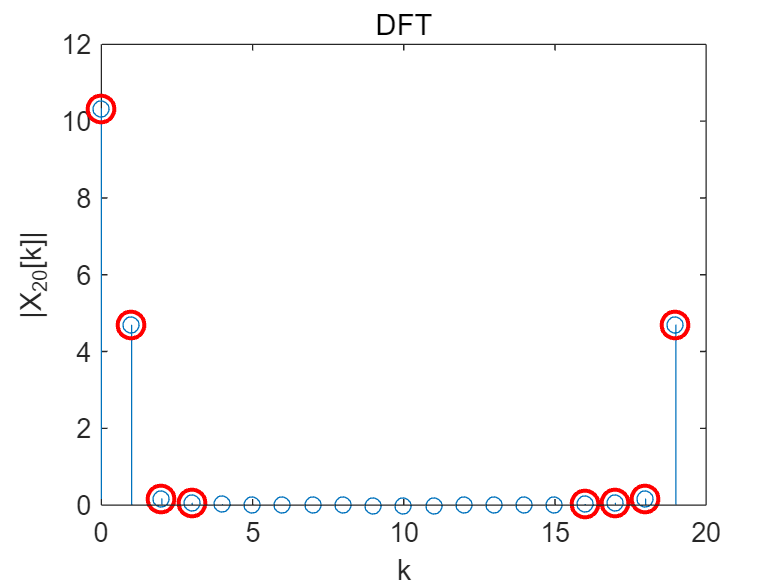

N = 20;
k = 0:N-1;
x = hamming(N);
X = DFTsum(x);
figure;
stem(k, abs(X));xlabel('k');ylabel('|X_{20}[k]|');title('DFT');
hold on;
low_freq_indices1 = 1:4;
plot(low_freq_indices1-1, abs(X(low_freq_indices1)), 'ro', 'MarkerSize', 10, 'LineWidth', 1.5);
low_freq_indices2 = 17:20;
plot(low_freq_indices2-1, abs(X(low_freq_indices2)), 'ro', 'MarkerSize', 10, 'LineWidth', 1.5);

hold off;

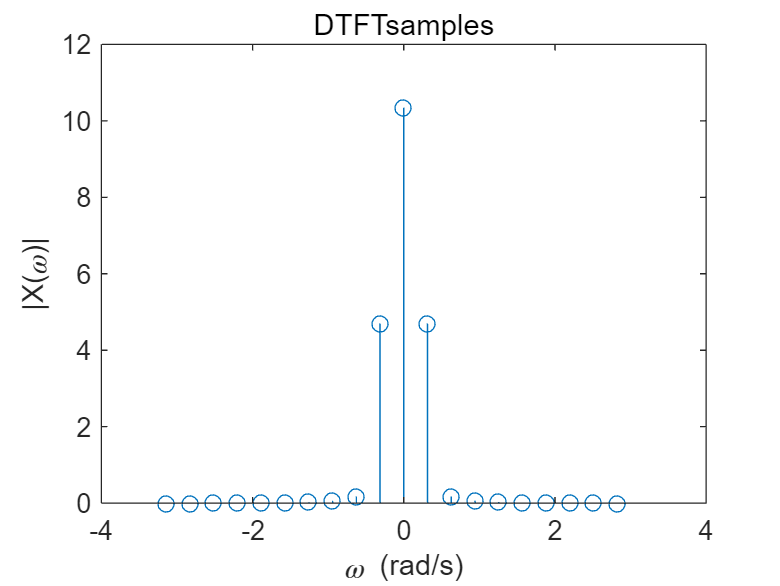


[X,w] = DTFTsamples(x);
figure;
stem(w, abs(X));xlabel('\omega (rad/s)');ylabel('|X(\omega)|');title('DTFTsamples');

## 5.2.2

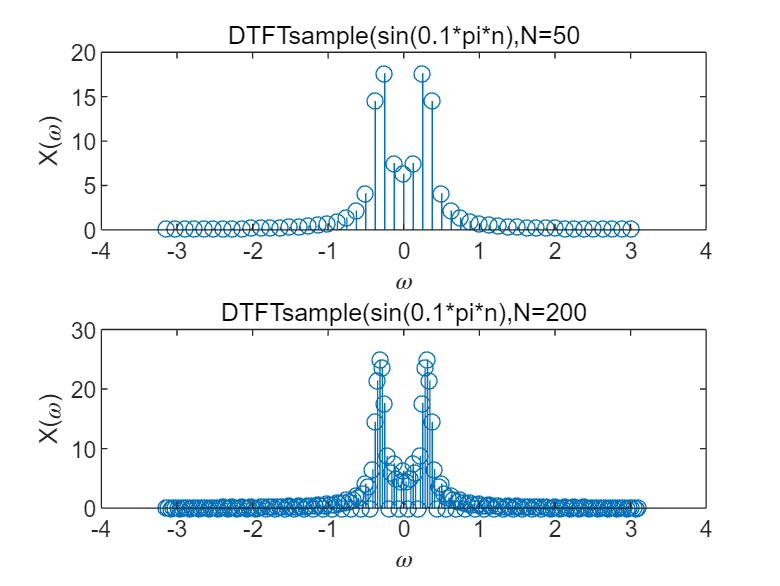

N = 50;
n = 0:N-1;
x = sin(0.1*pi*n).*(n>=0).*(n<=49);
[X,w] = DTFTsamples(x);
figure;
subplot(2,1,1),stem(w,abs(X)),xlabel('\omega'),ylabel('X(\omega)'),title('DTFTsample(sin(0.1*pi*n),N=50');
N = 200;
n = 0:N-1;
x = sin(0.1*pi*n).*(n>=0).*(n<=49);
[X,w] = DTFTsamples(x);
subplot(2,1,2),stem(w,abs(X)),xlabel('\omega'),ylabel('X(\omega)'),title('DTFTsample(sin(0.1*pi*n),N=200');

The second one is more like DTFT, for the true DTFT, it adds from - infinity  to + infinity. So the more zeros, the better. Why different? Zero padding, increase the sample rate.

## 5.3.1

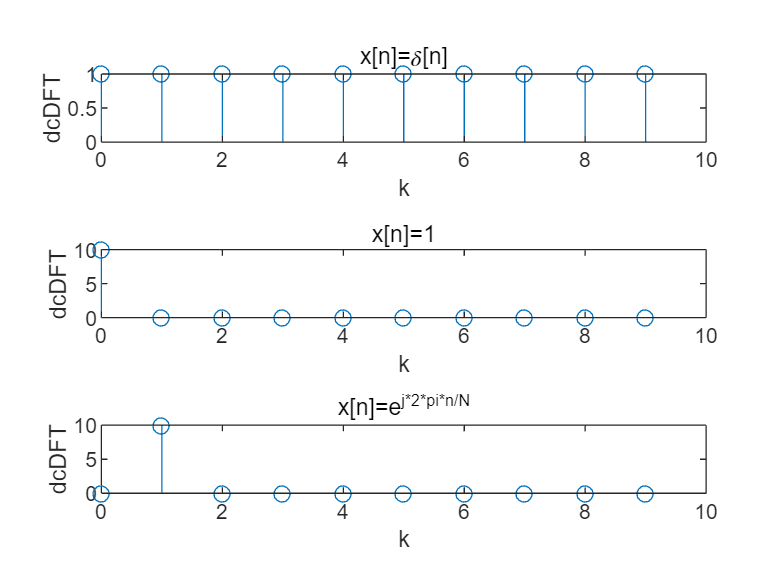

clc,clear,close all;
n = 0:9;
x1 = (n==0);
x2 = ones(1,10);
x3 = exp(1j*2*pi*n/10);
X1 = dcDFT(x1);
X2 = dcDFT(x2);
X3 = dcDFT(x3);
figure;
subplot(3,1,1),stem(n,abs(X1)),xlabel('k'),ylabel('dcDFT'),title('x[n]=\delta[n]');
subplot(3,1,2),stem(n,abs(X2)),xlabel('k'),ylabel('dcDFT'),title('x[n]=1');
subplot(3,1,3),stem(n,abs(X3)),xlabel('k'),ylabel('dcDFT'),title('x[n]=e^{j*2*pi*n/N}');

multiply:N+2*(N/2)^2=N+N^2/2

## 5.3.2

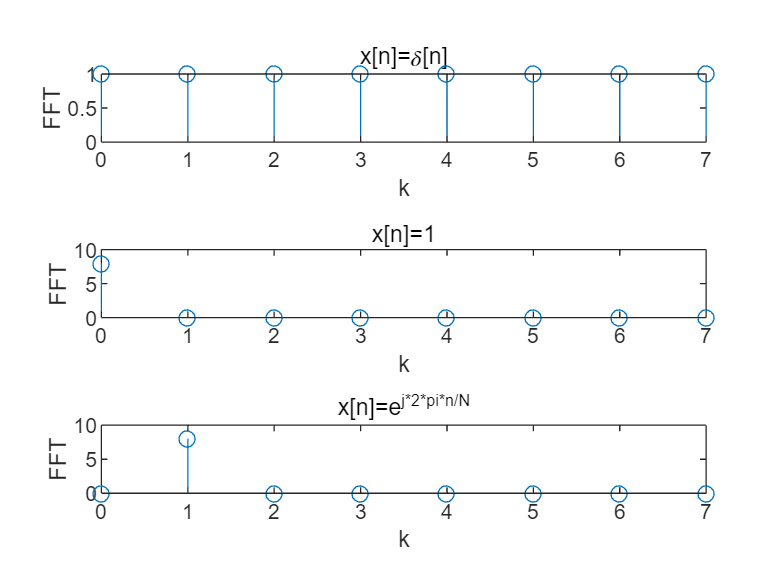

n = 0:7;
x1 = (n==0);
x2 = ones(1,8);
x3 = exp(1j*2*pi*n/8);
X1 = FFT8(x1);
X2 = FFT8(x2);
X3 = FFT8(x3);
figure;
subplot(3,1,1),stem(n,abs(X1)),xlabel('k'),ylabel('FFT'),title('x[n]=\delta[n]');
subplot(3,1,2),stem(n,abs(X2)),xlabel('k'),ylabel('FFT'),title('x[n]=1');
subplot(3,1,3),stem(n,abs(X3)),xlabel('k'),ylabel('FFT'),title('x[n]=e^{j*2*pi*n/N}');

FFT8(ones(1,8))

ans =      8     0     0     0     0     0     0     0


multiply:4+2*2+1*4=12

N=2^p, multiply times: N/2 * log2N = 2^(p-1) *p

traditional way, (2^10)^2=1048576, fft8,5120

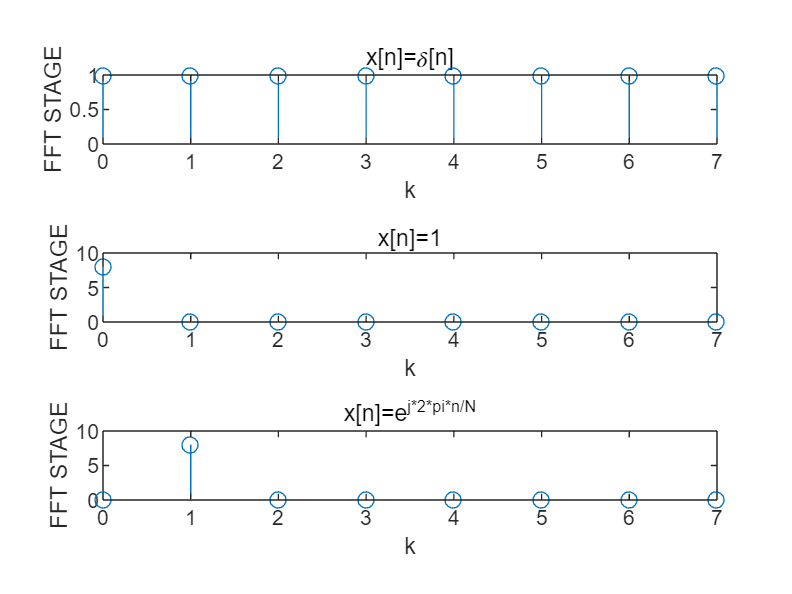

n = 0:7;
x1 = (n==0);
x2 = ones(1,8);
x3 = exp(1j*2*pi*n/8);
X1 = fft_stage(x1);
X2 = fft_stage(x2);
X3 = fft_stage(x3);
figure;
subplot(3,1,1),stem(n,abs(X1)),xlabel('k'),ylabel('FFT STAGE'),title('x[n]=\delta[n]');
subplot(3,1,2),stem(n,abs(X2)),xlabel('k'),ylabel('FFT STAGE'),title('x[n]=1');
subplot(3,1,3),stem(n,abs(X3)),xlabel('k'),ylabel('FFT STAGE'),title('x[n]=e^{j*2*pi*n/N}');

function X = DFTsum(x)
    N = length(x);
    X = zeros(1, N);
    for k = 1:N
        for n = 1:N
            X(k) = X(k) + x(n) * exp(-1j * 2 * pi * (k-1) * (n-1) / N);
        end
    end
end

function [X,w] = DTFTsamples(x)
    N = length(x);
    X = DFTsum(x);
    w = 2 * pi * ((0:N-1) - floor(N/2)) / N;
    X = fftshift(X);
end

function X = dcDFT(x)
    N = length(x);
    x0 = x(1:2:end);
    x1 = x(2:2:end);
    X0 = DFTsum(x0);
    X1 = DFTsum(x1);
    X0 = [X0 X0];
    X1 = [X1 X1];
    X = X0 + X1.*exp(-1j*2*pi/N*(0:N-1));
end

function X = FFT2(x)
    X(1) = x(1) + x(2);
    X(2) = x(1) - x(2);
end

function X = FFT4(x)
    X0 = FFT2([x(1) x(3)]);
    X1 = FFT2([x(2) x(4)]);
    temp = X1.*exp(-1j*2*pi/4*(0:1));
    X = [X0+temp X0-temp];
end

function X = FFT8(x)
    X0 = FFT4([x(1) x(3) x(5) x(7)]);
    X1 = FFT4([x(2) x(4) x(6) x(8)]);
    temp = X1.*exp(-1j*2*pi/8*(0:3));
    X = [X0+temp X0-temp];
end

function X = fft_stage(x)
    N = length(x);
    if N == 2
        X = zeros(1,2);
        X(1) = x(1) + x(2);
        X(2) = x(1) - x(2);
    else
        x0 = x(1:2:end);
        x1 = x(2:2:end);
        X0 = fft_stage(x0);
        X1 = fft_stage(x1);
        temp = X1 .* exp(-1j*2*pi/N*(0:N/2-1));
        X = [X0+temp X0-temp];
    end
end